# ergoCub Index Finger Identification and Control

Copyright (C) 2023 Fondazione Istitito Italiano di Tecnologia (IIT)

All Rights Reserved.

## System identification and modelling 

### Read datasets

#### Training set

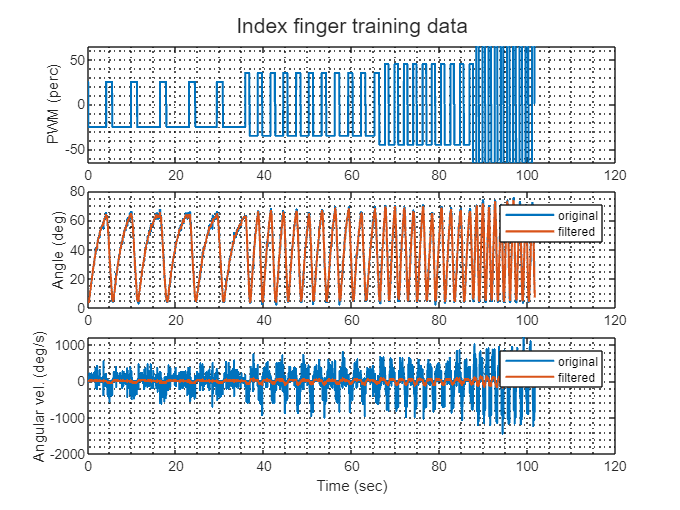

Ts = 0.01;
tau = 5;

training_table = prepare_dataset("data/training.csv", Ts, tau);

training_data = iddata(training_table.vel, training_table.pwm, Ts);
training_data.Name = "training";

figure('color', 'white');
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(training_table.Time, training_table.pwm);
ylabel("PWM (perc)")

h2 = nexttile;
plot(training_table.Time, training_table.pos_uf);
hold on
plot(training_table.Time, training_table.pos);
ylabel("Angle (deg)")
legend({"original", "filtered"})

h3 = nexttile;
plot(training_table.Time, training_table.vel_uf);
hold on
plot(training_table.Time, training_table.vel);

legend({"original", "filtered"})
ylabel("Angular vel. (deg/s)")
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle("Index finger training data")

#### Validation Set

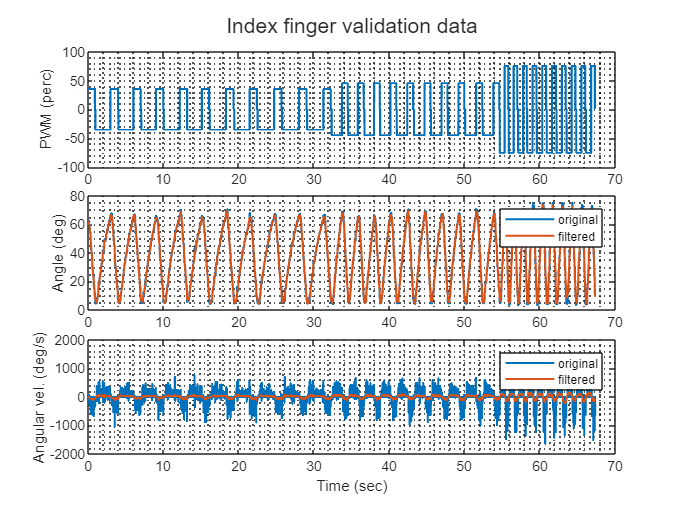

Ts = 0.01;
tau = 5;

validation_table = prepare_dataset("data/validation.csv", Ts, tau);

validation_data = iddata(validation_table.vel, validation_table.pwm, Ts);
validation_data.Name = "validation";

figure('color', 'white');
tiledlayout(3,1, "TileSpacing", "tight")

h1 = nexttile;
plot(validation_table.Time, validation_table.pwm);
ylabel("PWM (perc)")

h2 = nexttile;
plot(validation_table.Time, validation_table.pos_uf);
hold on
plot(validation_table.Time, validation_table.pos);
ylabel("Angle (deg)")
legend({"original", "filtered"})

h3 = nexttile;
plot(validation_table.Time, validation_table.vel_uf);
hold on
plot(validation_table.Time, validation_table.vel);

legend({"original", "filtered"})
ylabel("Angular vel. (deg/s)")
xlabel("Time (sec)")

linkaxes([h1 h2 h3], 'x')
sgtitle("Index finger validation data")

### Run identification as process model

We target a continuous LTI model in the form


$$\frac{y}{u} = \frac{k (s - z_1)}{(s - p_1) ( s - p_2)}$$


The poles can be real or complex conjugate.

opt = procestOptions;
opt.InitialCondition =  "zero";
model = procest(training_data, "P2ZU", opt);

s = tf('s');
finger_tf = tf(model);
zpk(finger_tf)

ans =
 
  From input "u1" to output "y1":
  -7.4961 (s+0.01042)
  --------------------
  (s+6.117) (s+0.2768)
 
Continuous-time zero/pole/gain model.
Model Properties


Plot results.

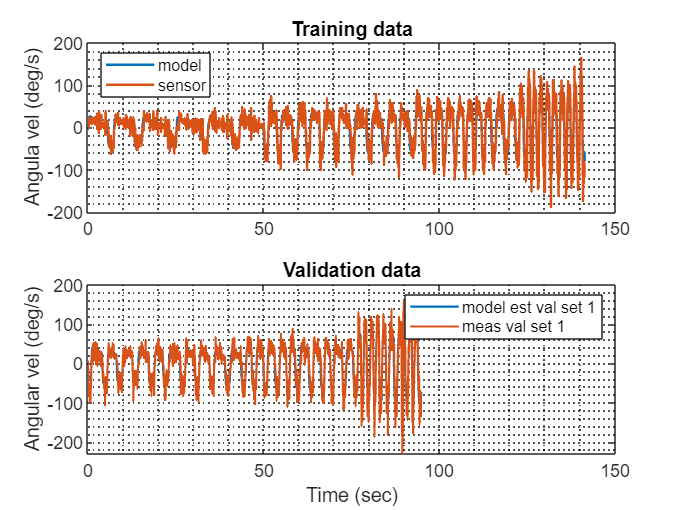

[rmse, fig_handle] = plot_results(finger_tf, training_data, validation_data, Ts, Ts);


disp(rmse)

     name: "Validation set 1 result"
    value: 20.1951873512431



### Add uncertainty

perc_uncertainty = 20;

finger_zpk = zpk(finger_tf);
poles = finger_zpk.P{1};
zeros = finger_zpk.Z{1};

upoles(1) = ureal("p1", poles(1), "Percentage", [-perc_uncertainty, perc_uncertainty]);
upoles(2) = ureal("p2", poles(2), "Percentage", [-perc_uncertainty, perc_uncertainty]);

uzero = ureal("z1", zeros, "Percentage", [-perc_uncertainty, perc_uncertainty]);

tfu = finger_zpk.K * (s - uzero) / ((s - upoles(1)) * (s - upoles(2)));

### Add integrator for position control

We change the IO relationship from  $\frac{\dot{\theta} }{u}$ to $\frac{\theta }{u}$  since we want to control the finger position.

tfu = tfu / s;

## Run autotuning

Here we define the specifications to tune the position controller in a robust way, and run the tuning algorithm.

#### Define tuning goals

Define the desired specifications.

Ts_controller = 1e-3;   % sec
responsetime = 0.3;     % sec
dcerror = 0.001;        % perc
peakerror = 1.02;       % fract relative
maxOvershoot = 2;       % perc
phase_margin = 80;      % deg
gain_margin = 3;        % dB

Define the goals.

tfu.InputName = "u";
tfu.OutputName = "y";

Rtrack = TuningGoal.Tracking('r', 'y', responsetime, dcerror, peakerror);
Rov = TuningGoal.Overshoot('r', 'y', maxOvershoot);
Rmargin = TuningGoal.Margins('y', gain_margin, phase_margin);

hard_goals = Rtrack;
soft_goals = [Rmargin, Rov];

#### Tune up the controller

Tune a PI controller. The D is zero since the system is highly damped due to friction.

[C, T] = design_robust_pid(tfu, soft_goals, hard_goals);

Plot tuning results.

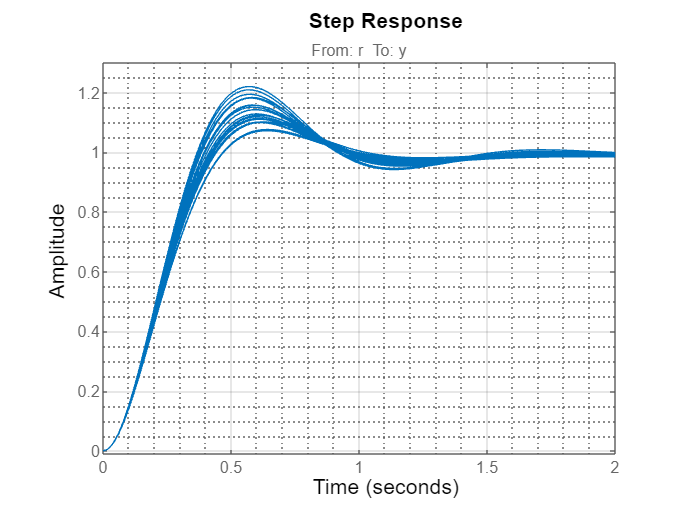

figure('color', 'white');
step(T, 2);
ylim([-0.01, 1.3])
grid('minor');

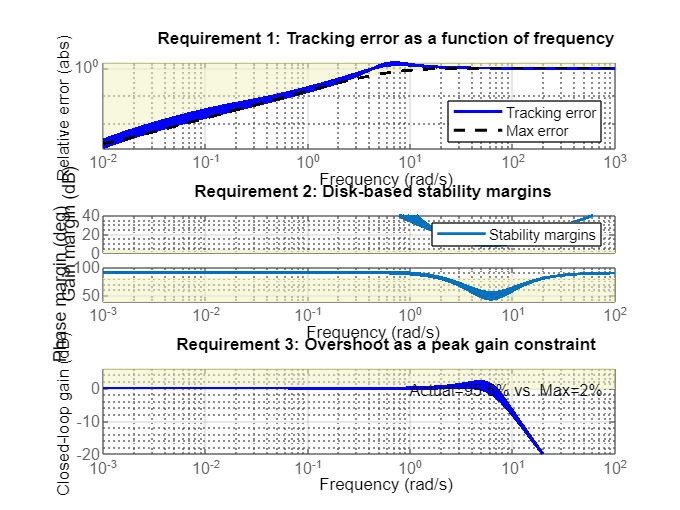


figure('color', 'white');
viewGoal([hard_goals soft_goals], T)

Get the discretized controller.

Cz = c2d(C, Ts_controller, 'tustin')

Cz =
 
            Ts*(z+1)
  Kp + Ki * --------
            2*(z-1) 

  with Kp = -4.95, Ki = -0.878, Ts = 0.001
 
Sample time: 0.001 seconds
Discrete-time PI controller in parallel form.
Model Properties
